## Cvičení 5: - Diferenciální rovnice

*Obrázek!!!!:*


$$U_0 =5V$$



$$L=1\mathrm{mH}$$



$$R=100\Omega$$


% U_0= 5;
% L = 1e-3;
% R = 100;
% 
% [t,i_L] = euler(@RL,0,0.1e-3,0,60);
% yyaxis right;
% plot(t,i_L);
% hold on;
% [t,i_L] = ode45(@RL,[0 0.1e-3],0);
% plot(t,i_L);
% grid on;
% xlabel("t (s)");
% ylabel("i (A)");
% title("Prechodovy dej v RL obvodu");
% 
% u_L = U_0 - i_L*R;
% yyaxis left;
% plot(t,u_L);
% ylabel("u_{L} (V)");
% legend("i_{L} pomocí eulera","i_{L} pomocí ode45","u_{L} pomocí ode45")

Přidání parametrů:

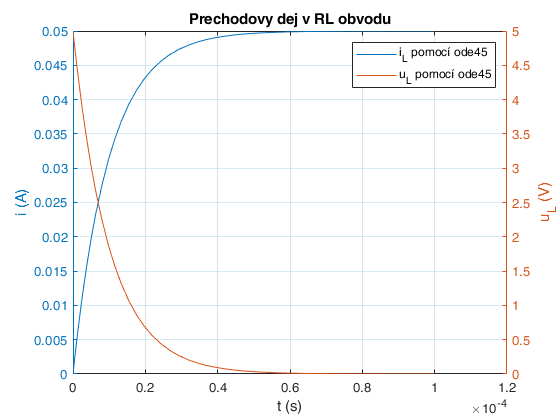

U_0 = 5;
L = 1e-3;
R = 100;


[t,i_L] = ode45(@(t,i_L) RL(t,i_L,U_0,R,L), [0 0.1e-3],0);
yyaxis left;
plot(t,i_L);
grid on;
hold on;
xlabel("t (s)");
ylabel("i (A)");
title("Prechodovy dej v RL obvodu");

u_L = U_0 - i_L*R;
yyaxis right;
plot(t,u_L);
ylabel("u_{L} (V)");
legend("i_{L} pomocí ode45","u_{L} pomocí ode45")

Různé počáteční podmínky a taky různé časy (zavolám ten výpočet prostě dvakrát za sebou s jinými poč.)